# FDFD 2D Solver for Scattering: Directional Coupler

A **directional coupler** is an optical device that transfers light between two closely spaced waveguides through evanescent coupling. It is commonly used for splitting or combining signals in photonic circuits, with applications in multiplexing, modulation, and switching.

In this example, we demonstrate the scattering field of a **2D directional coupler**. Wave is injected towards and propagates along the $+x$ direction. The relative permittivity is uniform along $z$ direction, i.e.,  $\varepsilon_r=\varepsilon_r(x,y)$. All materials in the simulation are assumed to be linear, homogeneous, and isotropic (LHI).

### Step 0: Global settings

The simulation begins with the initialization of a `Model2D` instance, followed by defining the global settings. The working plane is set to the **x-y plane** using the label `'xy'`, which specifies the 2D cross-sectional area for analysis. The simulation operates at a wavelength of **1.55 µm**, commonly used in optical communications. These global settings provide the foundation for defining the geometry and material properties in subsequent steps.

modelDC = Model2D.initialize();

Model2D: Object Initialized


modelDC.setLabel('xy'); % work on x-y plane
modelDC.setWavelength(1.55e-6); % work at 1.55 um wavelength

### Step 1: Device parameters

#### 1.1 Geometry parameters

The width of each waveguide is $0.48 \mu{\rm  m}$, with a gap of $0.2 \mu{\rm m}$ between them. One waveguide has a length of $80 \mu{\rm m}$, while the other one is $5 \mu{\rm m}$ shorter, providing an offset for the injection source. The total dimensions of the silicon dioxide cladding are $80 \mu{\rm m}$ in length and $3 \mu{\rm m}$ in width.

% geometry parameters [unit: m]
L = 80e-6; % total length
W = 3e-6; % total width
L_wg = 80e-6; % length of wavegudie
L_offset = 5e-6; % offset length
W_wg = 0.48e-6; % width of waveguide
W_gap = 0.2e-6; % width of gap

#### 1.2 Material information

The core waveguides are made of **silicon** while the surrounding cladding is made of **silicon dioxide**. At a wavelength of $1.55 \mu{\rm m}$ (the operating wavelength), the refractive indices are $n_{\rm Si} = 3.4712$ and $n_{\rm SiO_2} = 1.4434$.

eps_Si = 3.4712^2; % Silicon
eps_SiO2 = 1.4434^2; % Silicon dioxide

### Step 2: Build up simulation device

This step focuses on constructing the simulation domain by defining the geometric layout and material properties of the silicon dioxide background and silicon waveguides. Using the `Model2D` class, each device component is seamlessly created and configured, enabling an accurate representation of the directional coupler's physical structure.

#### 2.1 SiO2 background box

The first device is the **silicon dioxide (SiO₂) background**, which forms the cladding of the directional coupler.

modelDC.addDevice(1);
modelDC.setDevice(1).setGeometry('Rectangle', L, W, 'c', [L/2, 0]);
modelDC.setDevice(1).setMaterial(eps_SiO2);

#### 2.2 Si straight waveguides

The two silicon waveguides form the core components of the directional coupler. They enable the transfer of optical power through evanescent coupling, where light from one waveguide interacts with the other due to their close proximity. The asymmetry introduced by the offset in one waveguide helps to control the direction of injected source.

% Long waveguide
modelDC.addDevice(2);
modelDC.setDevice(2).setGeometry('Rectangle', L_wg, W_wg, 'bl', [0, W_gap/2]);
modelDC.setDevice(2).setMaterial(eps_Si);

% Short waveguide
modelDC.addDevice(3);
modelDC.setDevice(3).setGeometry('Rectangle', L_wg-L_offset, W_wg, 'tl', [L_offset, -W_gap/2]);
modelDC.setDevice(3).setMaterial(eps_Si);

#### 2.3 Complete device building

Once the components are added, the device-building process is finalized using `model.assembleDevice`. The `dispImg` method is called to visually confirm the constructed geometry.

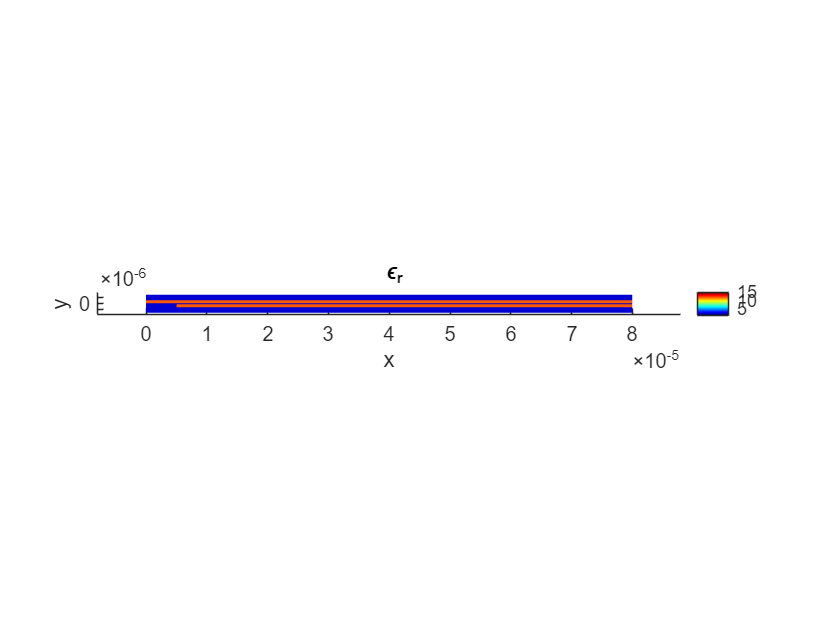

modelDC.assembleDevice;
modelDC.device.dispImg;

### Step 3: FDFD region mesh grid

The FDFD solver operates on a uniform mesh grid to discretize the simulation domain. Before meshing, the geometry is represented as a `polyshape` object. After meshing, it transforms into a discrete double array that captures the spatial distribution of relative permittivity $\varepsilon_r$ and relative permeability $\mu_r$.

The FDFD region is set in the $x-y$ plane, matching the silicon dioxide cladding box, with grid sizes of approximately ${\rm d}x \approx 44.42 {\rm nm}$ and ${\rm d}y \approx 14.92 {\rm nm}$. 

Nx = 1801;
Ny = 201;

dx = L/Nx;
dy = W/Ny;

modelDC.setMesh([Nx, Ny], [dx, dy], 'Center', [L/2, 0]);

### Step 4: Choose FDFD solver

We are going to solve a scattering problem. Therefore, we need to choose `'Scattering' `solver here.

A crucial aspect of the setup involves defining **Perfectly Matched Layers (PML)** around the device. These layers absorb outgoing waves and prevent reflections at the boundaries, ensuring accurate simulation results. The thickness of the PML must be carefully chosen—it should be sufficient to absorb waves effectively but not so thick that it interferes with the device region or reduces the free space available for wave propagation.

pml_thickness = [50,20];

modelDC.setSolver("Scattering", pml_thickness);

### Step 5: Set port

The port must be defined inside the FDFD region. As mentioned earlier, the input wave propagates along the $+x$ direction. The port is located at $x=3 \mu{\rm m}$ and spans from $y=-1 \mu{\rm m}$ to $y=1 \mu{\rm m}$, covering only the cross-section of the longer waveguide.

modelDC.addPort('+x', 3e-6, [-1e-6, 1e-6]); % unit: m

### Step 6: Configure input source

The input wave is configured to use the **fundamental transverse electric (TE) eigenmode** of the waveguide. This mode is selected due to its compatibility with the geometry and operating wavelength, ensuring efficient coupling and propagation.

- **Polarization**: TE (Transverse Electric) mode.

- **Mode Number**: Fundamental mode.

The `setSource` method configures the input source, and the resulting field distribution $|E_z|$ is visualized to confirm the setup.

polarization = 'TE'; % TE mode
num_mode = 1; % fundamental mode

modelDC.addSource("EigenMode", "ModeType", polarization, "ModeNum", num_mode);

Source has been set and ready to be used.


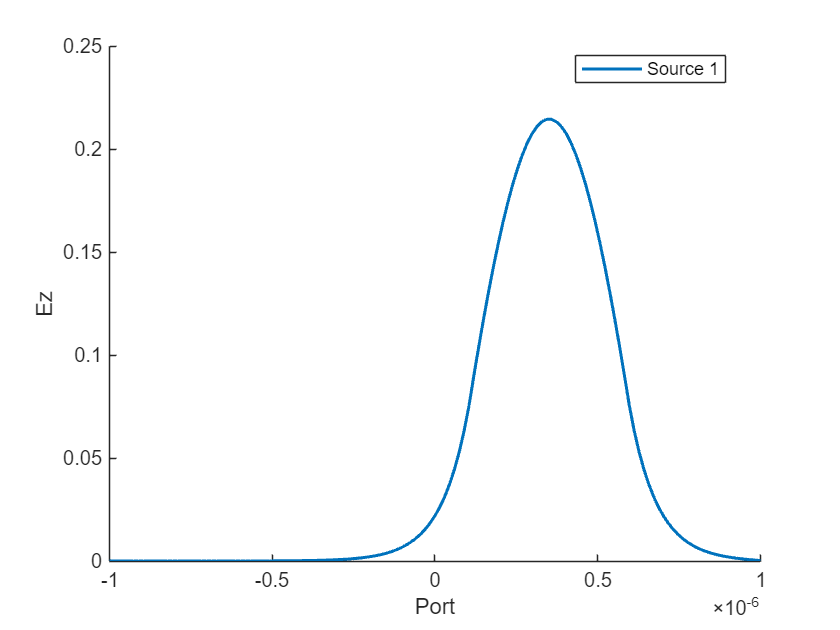

modelDC.source.dispProfile('Ez');

### Step 7: 2D scattering simulation

To simulate the scattering behavior of the directional coupler, the device must be fully meshed, and the input source properly configured. 

modelDC.solve;

The simulation is completed, to visualize the distribution of scattering field amplitude, $|E_z|$:

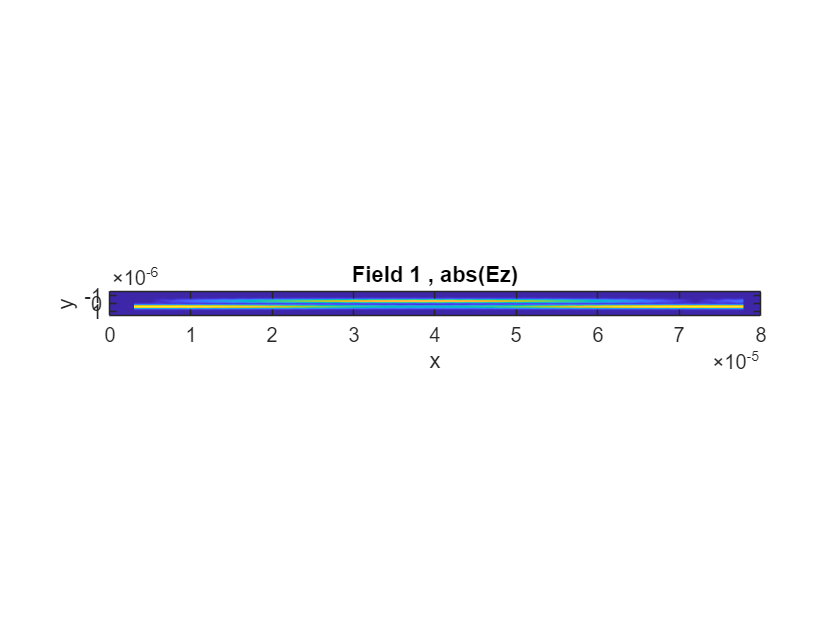

modelDC.dispField('Ez');

solution = modelDC.exportResult;

The results show smooth light propagation and efficient energy coupling between the waveguides. The gradual transfer of energy matches theoretical predictions, demonstrating the directional coupler’s functionality as intended.